# Analyze covid sequences inside database GISEID

% Load table containing just Date, Country and Continent
% File XallReducedMay2025 comes after applying procedure
% multialignHeader to the table (or to the vector of structures)
% which contain the fields
% Header and Sequence
% [T, indexWrongCountry, indexEmptyDate]= multialignHeader(X1)

load XallReducedMay2025
% size (X) = 15950908

## Manual insertion of Country Name and Continent 

% There are 142 for which automatic extraction of country
% was not possible
boo=X.Country=="NaN";
seq=1:size(X,1);
RowsWithWrongCountry=seq(boo);

% The first 10 rows are referred to France
% 'Spike|hCoV-19/Europe/France/ARA-CHUST-GIMAP
X{RowsWithWrongCountry(1:10),"Country"}="France";
X{RowsWithWrongCountry(1:10),"Continent"}="Europe";


% The other rows are referred to South Africa
% 'Spike|hCoV-19/Africa/Johannesburg-3043/2020|2020-06-15|EPI_ISL_14594740
X{RowsWithWrongCountry(11:end),"Country"}="South Africa";
X{RowsWithWrongCountry(11:end),"Continent"}="Africa";

% Check that there are no missing countries
assert(sum(X.Country=="NaN")==0,"Missing countries are still present")

## Remove the animals

boo=X.Country=="Animal";
% Number of animals inside the GISEID database (they are 2584)
disp(['Number of animals=' num2str(sum(boo))])

Number of animals=2584


X(boo,:)=[];
% Number of remaining rows = 15950908

## Pivot table of country and Date (by year)

JustEurope can be either false or true. If it is true just the countries belonging to Europe are analyzed.

justEurope=false;

if justEurope == true
    boo=X.Continent=="Europe";
    Xsel=X(boo,:);
else
    Xsel=X;
end
T1=pivot(Xsel,'Rows','Country','Columns','Date','ColumnsBinMethod','year','RowLabelPlacement','rownames');

## Get Population 2019-2022 for all the countries found in table T1

Source [https://github.com/datasets/population.git](https://github.com/datasets/population.git)

P=readtable("population.csv");

% Population every year
boo=P.Year>=2019 & P.Year<=2023;
P1=P(boo,:);
P1=pivot(P1,Rows="CountryName",Columns="Year",DataVariable="Value",RowLabelPlacement="rownames");
% setdiff(T1.Properties.RowNames,P1.Properties.RowNames)

% Country renaming
P1.Properties.RowNames("Czechia")="Czechoslovakia";
P1.Properties.RowNames("Egypt, Arab Rep.")="Egypt";
P1.Properties.RowNames("Bahamas, The")="Bahamas";
P1.Properties.RowNames("Brunei Darussalam")="Brunei";
P1.Properties.RowNames("Congo, Dem. Rep.")="Democratic Republic of Congo";
P1.Properties.RowNames("Congo, Rep.")="Congo";
P1.Properties.RowNames("Cabo Verde")="Cape Verde";
P1.Properties.RowNames("Gambia, The")="Gambia";
P1.Properties.RowNames("Hong Kong SAR, China")="Hong Kong";
P1.Properties.RowNames("Iran, Islamic Rep.")="Iran";
P1.Properties.RowNames("Kyrgyz Republic")="Kyrgyzstan";
P1.Properties.RowNames("Lao PDR")="Laos";
P1.Properties.RowNames("Micronesia, Fed. Sts.")="Micronesia (country)";
P1.Properties.RowNames("Russian Federation")="Russia";
P1.Properties.RowNames("St. Lucia")="Saint Lucia";
P1.Properties.RowNames("St. Martin (French part)")="Saint Martin (French part)";
P1.Properties.RowNames("St. Vincent and the Grenadines")="Saint Vincent and the Grenadines";
P1.Properties.RowNames("Slovak Republic")="Slovakia";
P1.Properties.RowNames("Korea, Rep.")="South Korea";
P1.Properties.RowNames("Syrian Arab Republic")="Syria";
P1.Properties.RowNames("Turkiye")="Turkey";
P1.Properties.RowNames("Virgin Islands (U.S.)")="United States Virgin Islands";
P1.Properties.RowNames("Venezuela, RB")="Venezuela";
P1.Properties.RowNames("Viet Nam")="Vietnam";
P1.Properties.RowNames("West Bank and Gaza")="Palestine";
P1.Properties.RowNames("Caribbean small states")="Bonaire Sint Eustatius and Saba";
P1.Properties.RowNames("Timor-Leste")="East Timor";

## Find the population for the countries not present inside population.csv

countriesNonPresent=setdiff(T1.Properties.RowNames,P1.Properties.RowNames);
if ~isempty(countriesNonPresent)
    % Source ChatGPT
    Year = (2017:2023)';
    AnguillaPopulation = [14425, 14721, 14823, 14843, 14475, 14180, 14410];
    FrenchGuianaPopulation = [268700, 276128, 281678, 285133, 286618, 288382, 290110];
    GuadeloupePopulation = [390253, 387629, 384239, 383559, 384315, 383569, 382733];
    MartiniquePopulation = [372594, 368783, 364508, 361225, 360749, 361019, 359202];
    MayottePopulation = [250143, 259621, 269579, 279696, 289039, 299336, 309901];
    MontserratPopulation = [4603, 4569, 4540, 4508, 4479, 4453, 4420];
    ReunionPopulation = [853659, 855961, 861210, 863083, 871157, 881348, 886453];
    SaintBarthelemyPopulation = [9793, 9850, 9900, 9950, 10000, 10050, 10100];
    SaintKittsNevisPopulation = [48614, 48857, 49101, 49347, 49593, 49841, 50090];
    TaiwanPopulation = [23571227, 23588932, 23603121, 23561236, 23375314, 23264640, 23420442];
    WallisFutunaPopulation = [11918, 11800, 11686, 11616, 11568, 11300, 11151];

    Pop=[AnguillaPopulation;FrenchGuianaPopulation;GuadeloupePopulation;MartiniquePopulation; ...
        MayottePopulation; MontserratPopulation; ReunionPopulation; SaintBarthelemyPopulation; ...
        SaintKittsNevisPopulation; TaiwanPopulation; WallisFutunaPopulation];
    PopT=array2table(Pop,"RowNames",countriesNonPresent,'VariableNames',string(Year));
    P2=[P1;PopT(:,3:7)];
else
    P2=P1;
end
CheckRem=setdiff(T1.Properties.RowNames,P2.Properties.RowNames);
if ~isempty(CheckRem)
    error("FSDA:missingData","Missing population for some country")
end
[~,~,ib]=intersect(T1.Properties.RowNames,P2.Properties.RowNames,'stable');
Pfin=P2(ib,:);

% T1 and Pfin must have the same RowNames
assert(isequal(T1.Properties.RowNames,Pfin.Properties.RowNames),"Missingnames")

## Get table with countries lat and long for the countries found in table T1

S=readtable('continents-according-to-our-world-in-data.xlsx');
S.Latitude=str2double(S.Latitude);
S.Longitude=str2double(S.Longitude);

assert(isempty(setdiff(T1.Properties.RowNames,S{:,1})),"Different RowNames")

## Load the corresponding shape file for the countried found in table T1

Files downloaded from  [https://www.naturalearthdata.com/downloads/](https://www.naturalearthdata.com/downloads/)

ShapeFile=readgeotable(['ShapeFiles' filesep 'ne_10m_admin_0_countries.shp']);

% Shape files for missing countries have been downloaded from
% https://gadm.org/download_country.html

load(['ShapeFiles' filesep 'ShapeFile2add'])
ShapeFile=[ShapeFile; S1];

% Tfin = table equal to T1 but with the addition of variables Entity Code
% Continents Latitude Longitude
% T1 = pivot table with country names
[~,~,ib]=intersect(T1.Properties.RowNames,S{:,1});
Tfin= [T1 S(ib,:)];

% Check that all the Shapes have been loaded
[CheckShape,iaa]=setdiff(string(Tfin.Code),string(ShapeFile.ADM0_A3));

if ~isempty(CheckShape)
    error("FSDA:missingData","Missing Shape for some country")
end

[inter,ia,ib]=intersect(string(Tfin.Code),string(ShapeFile.ADM0_A3),'stable');
ShapeFilefin=ShapeFile(ib,:);

## Find relative values 1000*number of cases/population

Trel=1000.*Tfin(:,1:5)./Pfin(:,1:5);

thresh=2;
year="2020";
boo=Trel{:,year}>thresh;
Trel{boo,year}=2;
year="2021";
Trel{Trel{:,year}>thresh,year}=thresh;
year="2022";
Trel{Trel{:,year}>thresh,year}=thresh;
year="2023";
Trel{Trel{:,year}>thresh,year}=thresh;

## Geobubble

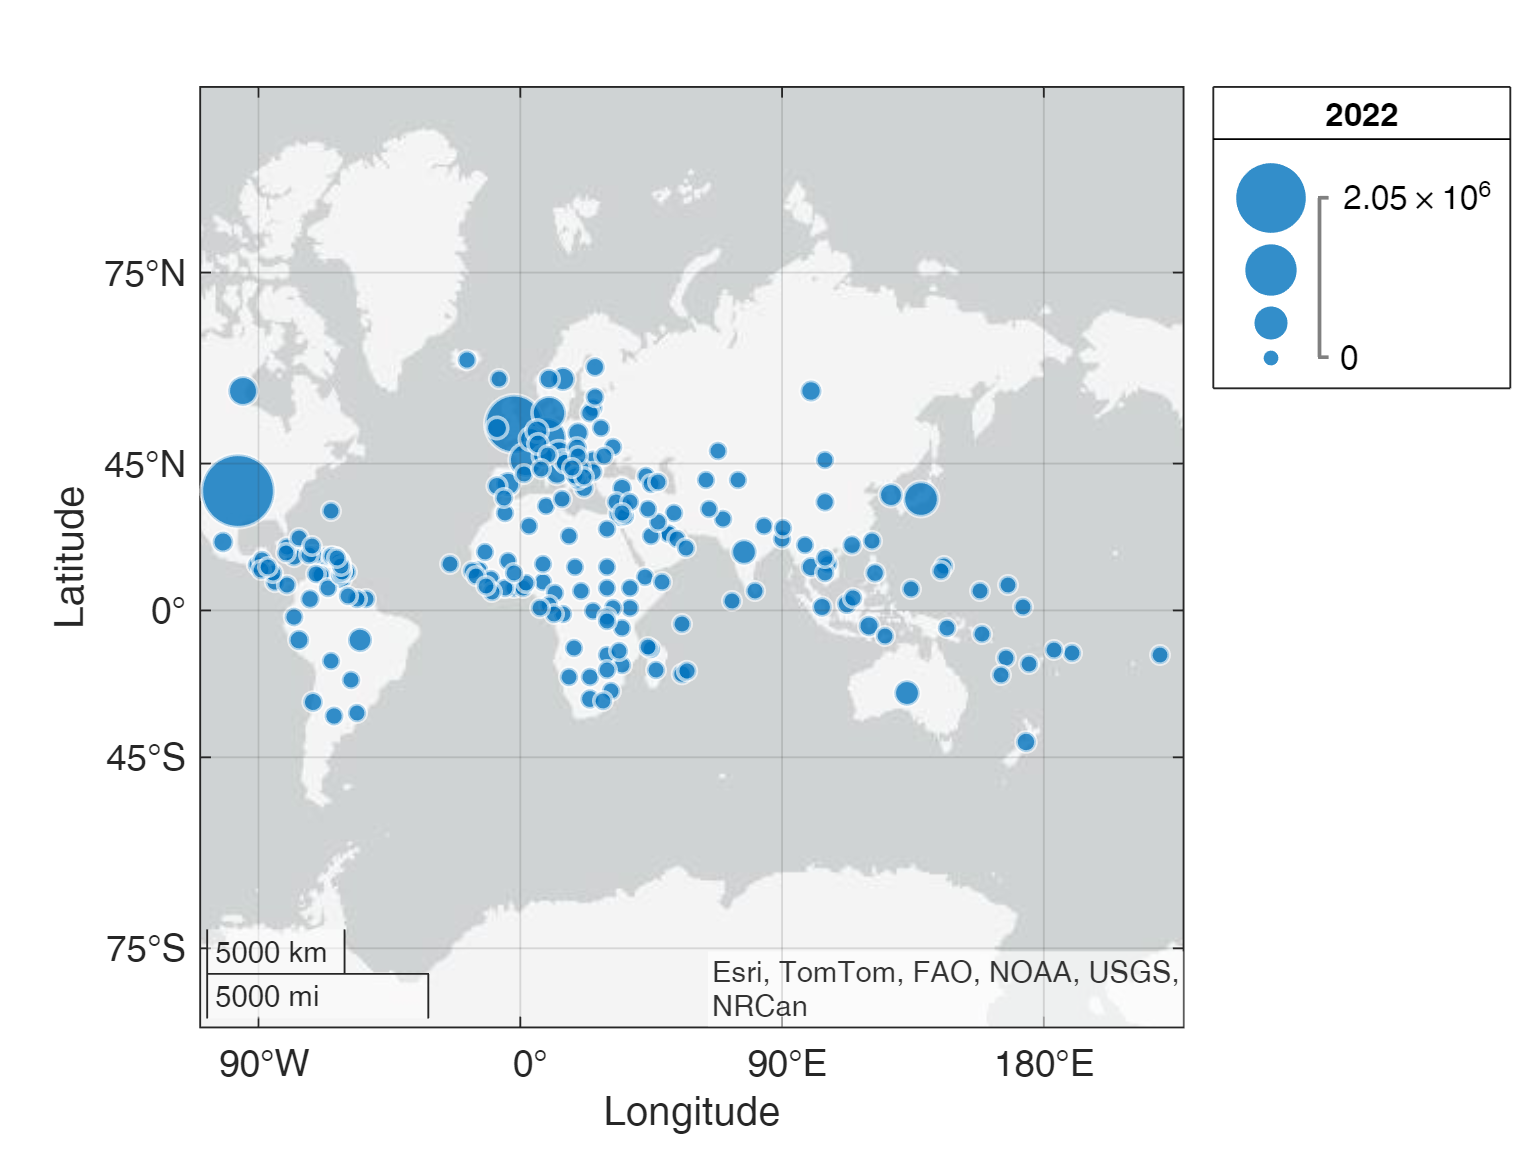


geobubble(Tfin,"Latitude","Longitude","SizeVariable","2022");

## Interactive geoplot

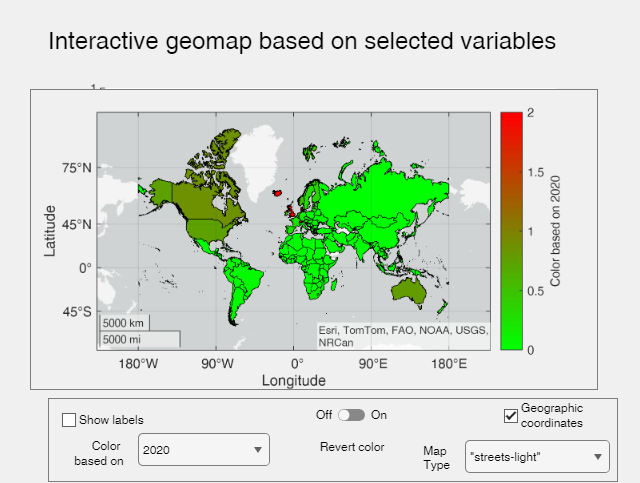

figure
geoplotFS(Trel(:,1:5),"2020",ShapeFilefin)